# assignment 3

## params

% init
close all;
clc;
% parameter
curb_weight = 1000; % kg
sprung_mass_w = 900;% kg
unsprung_mass = 25; % kg each wheel
Izz = 2000; % kg-m^2
Ixx = 750; % kg-m^2
wheel_base = 2.6; % m
a = 1.2; % m
b = wheel_base - a; % m
h_cg = 0.6; % m
h_cg_unsprung = 0.7; % m
h_roll_center = 0.2; %m

% tire
tire_C = 25000; % N/rad
vertcal_stiffness = 150000; % N/m
cf_absorb = 800; % N/m/s
cr_absorb = 1000; % N/m/s
dist_spring = 1.3; % m
dist_absorb = 1.3; % mor
installation_factor = 1;

## Part 1

### Q1

Q1.1.a

% omega
omega_f = 1.1*2*pi; % hz -> rad/s

mf = sprung_mass_w*b/2/wheel_base

mf = 242.3077

kf = omega_f^2*mf

kf = 1.1575e+04

Q1.1.b

% omega
omega_r = 1.3*2*pi; % hz -> rad/s
mr = sprung_mass_w*a/2/wheel_base

mr = 207.6923

kr = omega_r^2*mr

kr = 1.3857e+04

Q1.2.a

kkf = 1/(1/kf+1/vertcal_stiffness)

kkf = 1.0746e+04

dp_ratio_f = cf_absorb/2/sqrt(kkf*mf)

dp_ratio_f = 0.2479


kkr = 1/(1/kr+1/vertcal_stiffness)

kkr = 1.2685e+04

dp_ratio_r = cr_absorb/2/sqrt(kkr*mr)

dp_ratio_r = 0.3080

plot the picture

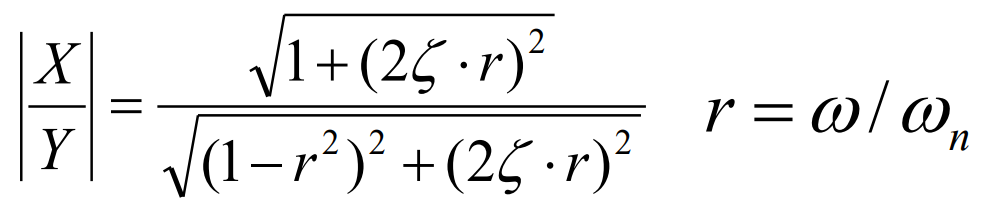

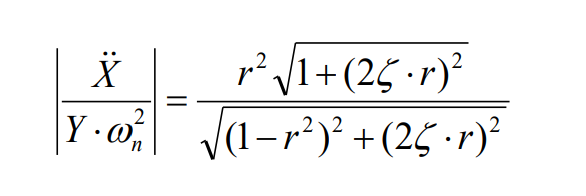

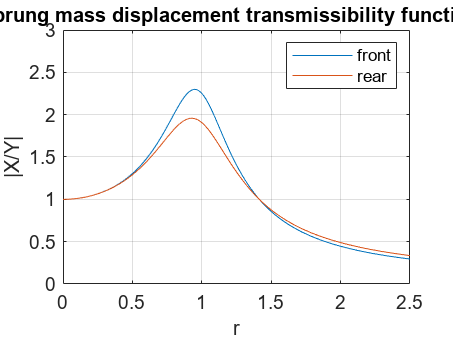

r = 0:.01:2.5;
% 1 DOF
% with frequency omega_f
y1 = sqrt(1+(2*dp_ratio_f.*r).^2)./sqrt((1-r.^2).^2+(2*dp_ratio_f.*r).^2);
yy1 = r.^2.*sqrt(1+(2*dp_ratio_f.*r).^2)./sqrt((1-r.^2).^2+(2*dp_ratio_f.*r).^2);

% with frequency omega_r
y2 = sqrt(1+(2*dp_ratio_r.*r).^2)./sqrt((1-r.^2).^2+(2*dp_ratio_r.*r).^2);
yy2 = r.^2.*sqrt(1+(2*dp_ratio_r.*r).^2)./sqrt((1-r.^2).^2+(2*dp_ratio_r.*r).^2);

% plot
figure(1)
plot(r,y1);
hold on
plot(r,y2);

ylim([0 3])
title("sprung mass displacement transmissibility functions");
legend('front','rear')
xlabel("r");
ylabel("|X/Y|");
grid on 
hold off;

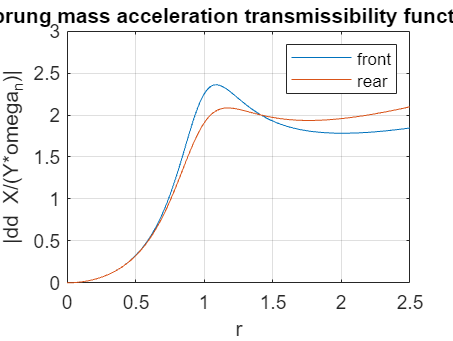


figure(2)
plot(r,yy1);
hold on
plot(r,yy2);
ylim([0 3])
title("sprung mass acceleration transmissibility functions");
legend('front','rear')
xlabel("r");
ylabel("|dd X/(Y*omega_n)|");
grid on 
hold off;

Q1.2.b

% params 
magnitude = '0.1'; % m
wavelength = 1.2; % m
velocity1 = 5/3.6; % kph->m/s^2
velocity2 = 50/3.6; % kph->m/s^2

### Q2

Q2.1

k_us = -(curb_weight*a*tire_C-curb_weight*b*tire_C)/(wheel_base*tire_C*tire_C)

k_us = 0.0031

Q2.2

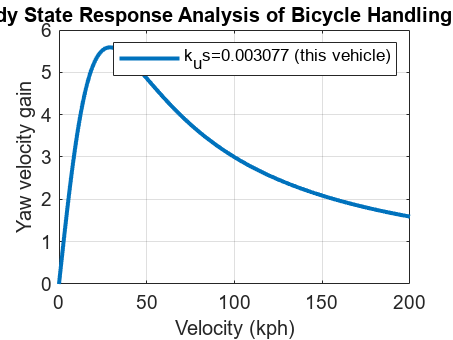

velocity=0:0.2:200;
u=velocity*3.6;
yaw_v_gain = u./(wheel_base+k_us*u.^2);
yaw_v_gain_neutral = u./(wheel_base);

% plot
plot(u,yaw_v_gain,'LineWidth',2);

title("Steady State Response Analysis of Bicycle Handling Model");
legend('k_us=0.003077 (this vehicle)');
xlabel("Velocity (kph)");
ylabel("Yaw velocity gain");
xlim([0 200])
ylim([0 6])
grid on;
hold off

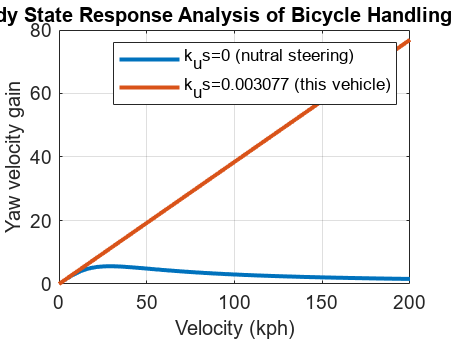


% double plot
plot(u,yaw_v_gain,'LineWidth',2);
hold on;
plot(u,yaw_v_gain_neutral,'LineWidth',2);

title("Steady State Response Analysis of Bicycle Handling Model");
legend('k_us=0 (nutral steering)','k_us=0.003077 (this vehicle)');
xlabel("Velocity (kph)");
ylabel("Yaw velocity gain");
xlim([0 200])
ylim([0 80])
grid on;
hold off

### Q3

rss = 2; % degree/s